# Lab 2 - Visión por Computador

**Juan Carlos Soriano (1493037) - Jorge Giménez (1493035)**

Primeramente, cargamos y mostramos la imagen sobre la que queremos aplicar el algoritmo.

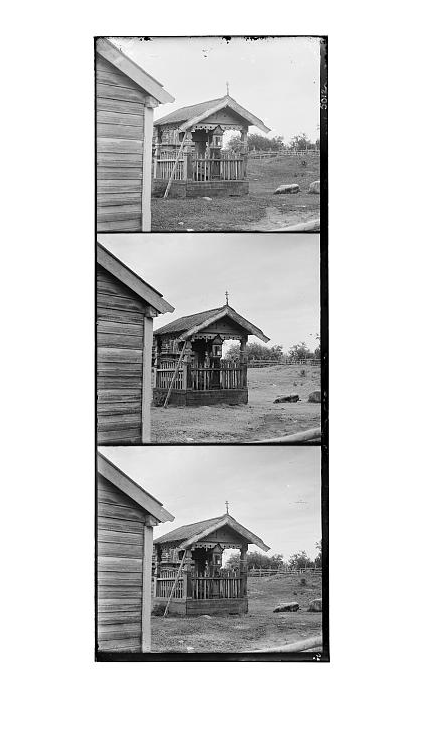

clear
clc

imagePath = "./inputImage2.jpg";
inputImage = im2double(imread(imagePath));
imshow(inputImage, []);

### 1- Segmentación de las 3 *subimágenes*

El primer paso será conseguir separar las 3 *subimágenes* de la* imagen total* (esta imagen vertical que contiene 3 imágenes más pequeñas dentro suyo que podemos ver al principio del *script* al ejecutarlo).

En el siguiente código se hacen las siguientes asunciones:

- Que las *subimágenes* están eprfectamente colocadas ocupando cada una 1/3 de la *imagen total*.

- Que se ordenan en el orden BGR de arriba hacía abajo (encontraod en la web).

tmp = size(inputImage);
subImageHeight = floor(tmp(1)/3);

channelB = inputImage(1:subImageHeight,:);
channelG = inputImage(subImageHeight+1:subImageHeight*2,:);
channelR = inputImage((subImageHeight*2)+1:subImageHeight*3,:);

Podemos visualizar las 3 *subimágenes *obtenidas mediante esta segmentación tan sencilla:

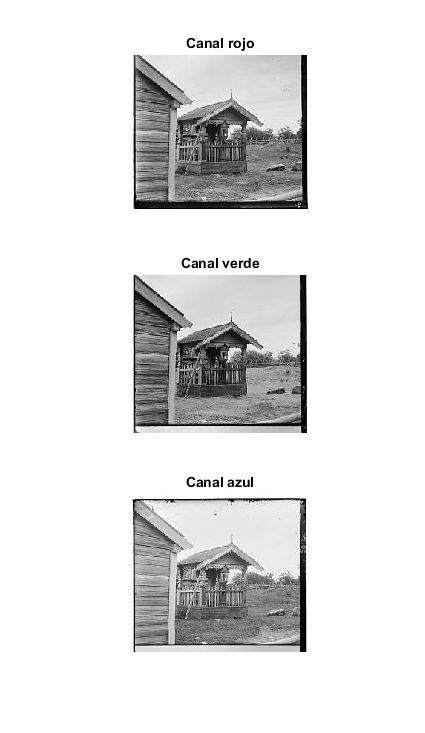

subplot(3, 1, 1);
imshow(channelR);
title("Canal rojo")
subplot(3, 1, 2);
imshow(channelG);
title("Canal verde")
subplot(3, 1, 3);
imshow(channelB);
title("Canal azul")

figure

Si superponemos las imagenes en el orden correcto tal y como las habríamos obtenido ahora, tedríamos el siguiente resultado:

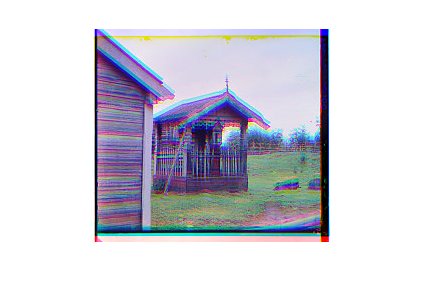

uncenteredComposition = cat(3, channelR, channelG, channelB);
imshow(uncenteredComposition);

Se puede ver como la imagen toma color pero no se ve demasiado bien debido a que los 3 canales no acaban de estar bien centrados entre si.

### 2- Centrado de las 3 *subimágenes*

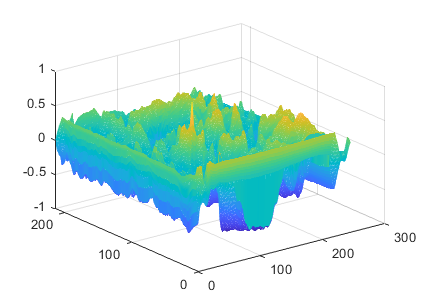

kernelCenter = [70 70];
kernelRadius = 10;
tmp = [kernelCenter(1)-kernelRadius, kernelCenter(1)+kernelRadius; kernelCenter(2)-kernelRadius, kernelCenter(2)+kernelRadius];
kernel = channelR(tmp(1,1):tmp(1,2),tmp(2,1):tmp(2,2));

displacementVectorG = getMatchCoordinates(kernel, channelG) - kernelCenter;

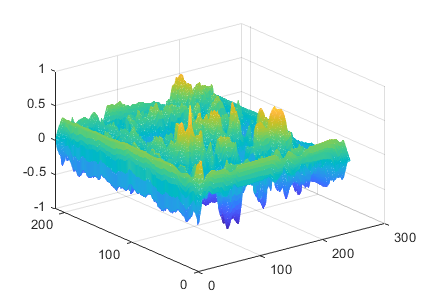

displacementVectorB = getMatchCoordinates(kernel, channelB) - kernelCenter;

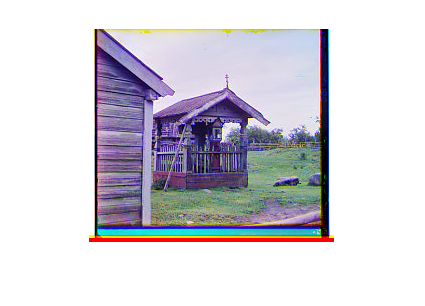


maxDisplacementV = max(abs(displacementVectorG(1)), abs(displacementVectorB(1)));
maxDisplacementH = max(abs(displacementVectorG(2)), abs(displacementVectorB(2)));

tmp = size(channelR);
finalComposition = zeros(tmp(1), tmp(2), 3);
finalComposition = padarray(finalComposition, [maxDisplacementV maxDisplacementH], 0);

finalComposition(1+maxDisplacementV:maxDisplacementV+tmp(1), 1+maxDisplacementH:maxDisplacementH+tmp(2), 1) = channelR;
finalComposition(1+maxDisplacementV:maxDisplacementV+tmp(1), 1+maxDisplacementH:maxDisplacementH+tmp(2), 2) = channelG;
finalComposition(:,:,2) = circshift(finalComposition(:,:,2), -displacementVectorG);
finalComposition(1+maxDisplacementV:maxDisplacementV+tmp(1), 1+maxDisplacementH:maxDisplacementH+tmp(2), 3) = channelB;
finalComposition(:,:,3) = circshift(finalComposition(:,:,3), -displacementVectorB);

crop = centerCropWindow2d(size(finalComposition), size(channelR));
finalComposition = imcrop(finalComposition, crop);
imshow(finalComposition)

function maxCorrelationCoordinates = getMatchCoordinates(kernel, imageChannel)
correlation = normxcorr2(kernel, imageChannel);
crop = centerCropWindow2d(size(correlation), size(imageChannel));
correlation = imcrop(correlation, crop);
mesh(correlation);
[~, maxCorrelationIndex] = max(correlation(:));
[v, h] = ind2sub(size(imageChannel), maxCorrelationIndex);
maxCorrelationCoordinates = [v h];
end

% Para mostrar las coincidencias del kernel en los demás 
%{
subplot(1,3,1)
imshow(r(rCoordinates(1)-kernelRadius:rCoordinates(1)+kernelRadius,rCoordinates(2)-kernelRadius:rCoordinates(2)+kernelRadius),[]);
title("R channel - (" + rCoordinates(1) + "," + rCoordinates(2) + ")")
subplot(1,3,2)
imshow(g(gCoordinates(1)-kernelRadius:gCoordinates(1)+kernelRadius,gCoordinates(2)-kernelRadius:gCoordinates(2)+kernelRadius),[]);
title("G channel - (" + gCoordinates(1) + "," + gCoordinates(2) + ")")
subplot(1,3,3)
imshow(b(bCoordinates(1)-kernelRadius:bCoordinates(1)+kernelRadius,bCoordinates(2)-kernelRadius:bCoordinates(2)+kernelRadius),[]);
title("B channel - (" + bCoordinates(1) + "," + bCoordinates(2) + ")")
%}